# score factor algrothim

## read info

For all methods we normalize scores above 100 to be exactly 100. 

load('C:\Users\eladz\Documents\workProjects\matlab_scripts\teach\phys4bio_77133_2022_gradeTab.mat')
scores=table2array(gradesallunified);

% remove empty first line 
scores=scores(2:end,:);


ids=scores(:,1); % id numbers 
len=length(ids);
partI=scores(:,2:12);
partII=scores(:,13:19);

%unique(sum(partI,2))
%unique(sum(partII,2))

## Untouched values

The following graphs show the score as they are now. 

Failing threshold is taken to be a score of 55 (dotted line)

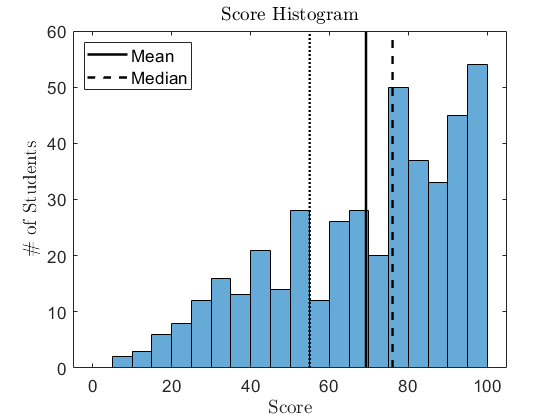

finScore=sum(partI,2)+sum(partII,2);
finScore(finScore>100)=100;

lw=1.8;


h=[];
figure


hs=histogram(finScore,0:5:100);
hold on
h(1)=plot(mean(finScore).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
h(2)=plot(median(finScore).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

%xlabelmine('Score');
ylabelmine('\# of Students');
ylim([0 60])
legend(h,'location','northwest','fontsize',13)
set(gca,'fontsize',13)
xlabelmine('Score');
titlemine('Score Histogram');

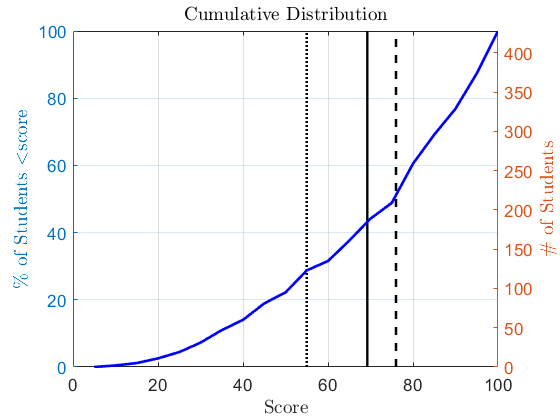


cs=cumsum(hs.Values);
figure;
yyaxis left
plot(5:5:100,100.*cs./len,'b','LineWidth',2)
hold on
plot(mean(finScore).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
plot(median(finScore).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

grid

ylabelmine('\% of Students $<$score');
 yyaxis right
 plot(5:5:100,cs,'b','LineWidth',2)
 ylim([0 len])
% 
 ylabelmine('\# of Students');
xlabelmine('Score');
set(gca,'fontsize',13)
titlemine('Cumulative Distribution');

%t.Padding='tight';
%t.TileSpacing='compact';

fprintf('average score: %4.1f \n',mean(finScore))

average score: 69.3 


fprintf('median score: %4.1f \n',median(finScore))

median score: 76.0 


fprintf('Number of fails (<55): %4.1f (%4.1f %%)\n',sum(finScore<55),100.*sum(finScore<55)./len)

Number of fails (<55): 123.0 (28.7 %)


## Reuven's method

Reuvan's Algorith: new score = score + alpha*(100-score), with alpha=0.2

Also shown in thin lines the results for alpha=0.15 and alpha=0.25 in the second graph.

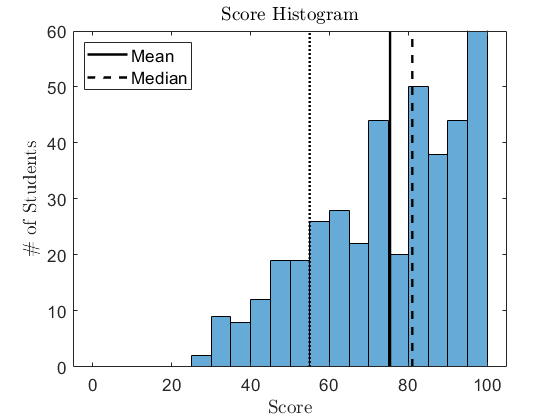

alf=0.2;

scoreR=(finScore+alf.*(100-finScore));
scoreR15=(finScore+0.15.*(100-finScore));
scoreR25=(finScore+0.25.*(100-finScore));

h=[];
figure
hs=histogram(scoreR,0:5:100);
hold on
h(1)=plot(mean(scoreR).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
h(2)=plot(median(scoreR).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

xlabelmine('Score');
ylabelmine('\# of Students');
ylim([0 60])
legend(h,'location','northwest','fontsize',13)
set(gca,'fontsize',13)
titlemine('Score Histogram');

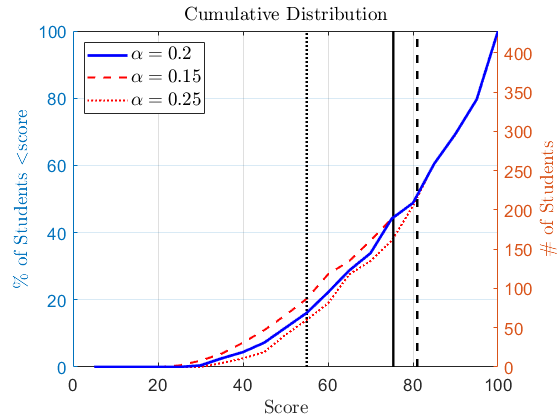


csR=cumsum(hs.Values); 
csR15=cumsum(histcounts(scoreR15,0:5:100));
csR25=cumsum(histcounts(scoreR25,0:5:100));
figure;
h=[];
yyaxis left
h(1)=plot(5:5:100,100.*csR./len,'b','LineWidth',2,...
    'DisplayName','$\alpha=0.2$');
hold on
h(2)=plot(5:5:100,100.*csR15./len,'r--','LineWidth',1.5,...
    'DisplayName','$\alpha=0.15$');
h(3)=plot(5:5:100,100.*csR25./len,'r:','LineWidth',1.5,...
    'DisplayName','$\alpha=0.25$');


plot(mean(scoreR).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
plot(median(scoreR).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

grid

ylabelmine('\% of Students $<$score');


 yyaxis right
h(4)=plot(5:5:100,csR,'b','LineWidth',2);
 ylim([0 len])
legend(h(1:3),'Interpreter','latex','location','northwest','fontsize',14)
 
 xlabelmine('Score');
 ylabelmine('\# of Students');
set(gca,'fontsize',13)
titlemine('Cumulative Distribution');

fprintf('average score: %4.1f \n',mean(scoreR))

average score: 75.4 


fprintf('median score: %4.1f \n',median(scoreR))

median score: 81.0 


fprintf('Number of fails (<55): %4.1f (%4.1f %%) \n',sum(scoreR<55),100.*sum(scoreR<55)./len)

Number of fails (<55): 69.0 (16.1 %) 


## Amir's method

The implementation of this method is as follows: 

1) find the total score for part 1 (multiples of 6 between 0 and 54)

2) Change every 54 to a 48. 

3) multiply by 54/48 (1.125) to preserve a total score of 54 for that part. 

4) repeat for part II: score 50 turns into 40, multiply by 50/40 (1.25);

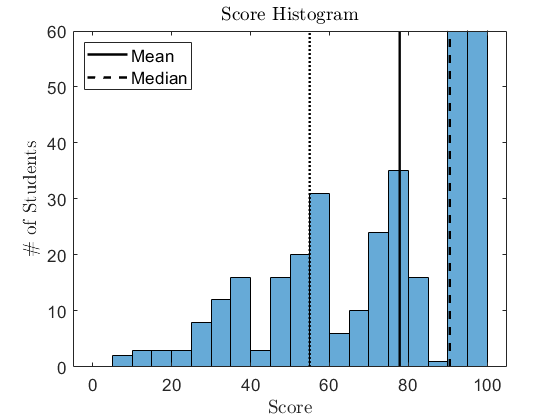

p1=sum(partI,2);
p2=sum(partII,2);

p1(p1==54)=48;
p2(p2==50)=40;

scoreA=p1.*54/48+p2.*50/40;
scoreA(scoreA>100)=100;
h=[];
figure
hs=histogram(scoreA,0:5:100);
hold on
h(1)=plot(mean(scoreA).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
h(2)=plot(median(scoreA).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

xlabelmine('Score');
ylabelmine('\# of Students');
ylim([0 60])
legend(h,'location','northwest','fontsize',13)
set(gca,'fontsize',13)
titlemine('Score Histogram');

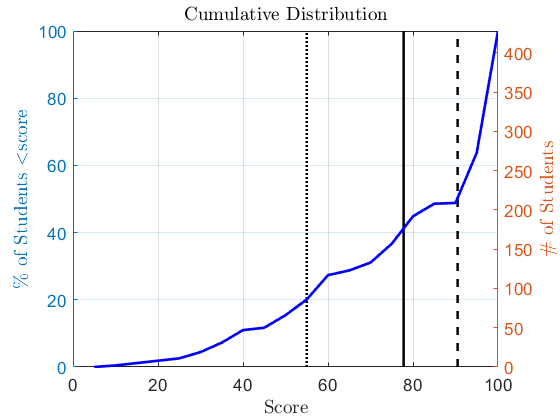


csA=cumsum(hs.Values);
figure;
yyaxis left
plot(5:5:100,100.*csA./len,'b','LineWidth',2)
hold on
plot(mean(scoreA).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
plot(median(scoreA).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

grid

ylabelmine('\% of Students $<$score');


 yyaxis right
 plot(5:5:100,csA,'b','LineWidth',2)
 ylim([0 len])
xlabelmine('Score');
 ylabelmine('\# of Students');

set(gca,'fontsize',13)
titlemine('Cumulative Distribution');

fprintf('average score: %4.1f \n',mean(scoreA))

average score: 77.8 


fprintf('median score: %4.1f \n',median(scoreA))

median score: 90.5 


fprintf('Number of fails (<55): %4.1f (%4.1f %%) \n',sum(scoreA<55),100.*sum(scoreA<55)./len)

Number of fails (<55): 86.0 (20.1 %) 


## simple method - Add 10 points

For comparison - just add a constant 10 point to all students (as always scores above 100 equal 100). 

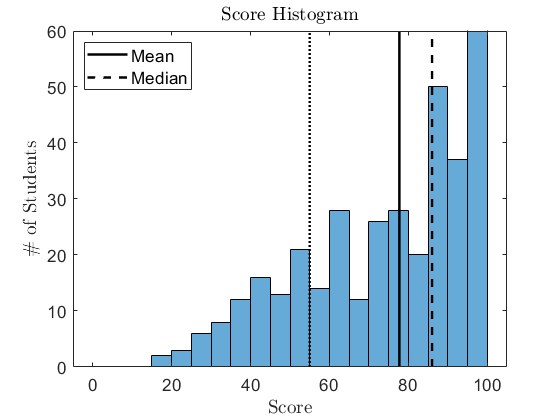

ff=10;
scoreS=finScore+ff;
scoreS(scoreS>100)=100;

h=[];
figure
hs=histogram(scoreS,0:5:100);
hold on
h(1)=plot(mean(scoreS).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
h(2)=plot(median(scoreS).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

xlabelmine('Score');
ylabelmine('\# of Students');
ylim([0 60])
legend(h,'location','northwest','fontsize',13)
set(gca,'fontsize',13)
titlemine('Score Histogram');

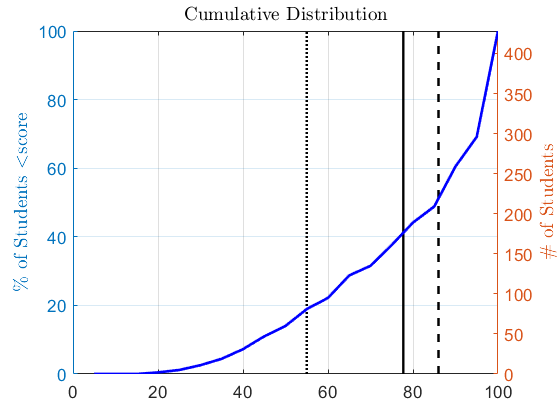


csS=cumsum(hs.Values);
figure;
yyaxis left
plot(5:5:100,100.*csS./len,'b','LineWidth',2)
hold on
plot(mean(scoreS).*[1 1],[0 100],'k-','linewidth',lw,...
    'DisplayName','Mean');
plot(median(scoreS).*[1 1],[0 100],'k--','linewidth',lw,...
    'DisplayName','Median');
plot(55.*[1 1],[0 100],'k:','linewidth',lw);

grid

ylabelmine('\% of Students $<$score');


 yyaxis right
 plot(5:5:100,csS,'b','LineWidth',2)
 ylim([0 len])
% 
 ylabelmine('\# of Students');
set(gca,'fontsize',13)
titlemine('Cumulative Distribution');


fprintf('average score: %4.1f \n',mean(scoreS))

average score: 77.7 


fprintf('median score: %4.1f \n',median(scoreS))

median score: 86.0 


fprintf('Number of fails (<55): %4.1f (%4.1f %%) \n',sum(scoreS<55),100.*sum(scoreS<55)./len)

Number of fails (<55): 81.0 (18.9 %) 


## Comparison of methods

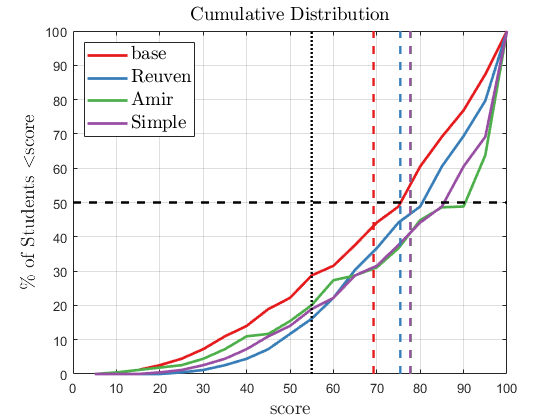

colors=brewermap(8,'Set1');
 
 figure;
%yyaxis left
h(1)=plot(5:5:100,100.*cs./len,'Color',colors(1,:),'LineWidth',2,'DisplayName','base');
hold on
h(2)=plot(5:5:100,100.*csR./len,'Color',colors(2,:),'LineWidth',2,'DisplayName','Reuven');
h(3)=plot(5:5:100,100.*csA./len,'Color',colors(3,:),'LineWidth',2,'DisplayName','Amir');
h(4)=plot(5:5:100,100.*csS./len,'Color',colors(4,:),'LineWidth',2,'DisplayName','Simple');

plot(mean(finScore).*[1 1],[0 100],'--','Color',colors(1,:),'linewidth',lw)
plot(mean(scoreR).*[1 1],[0 100],'--','Color',colors(2,:),'linewidth',lw)
plot(mean(scoreA).*[1 1],[0 100],'--','Color',colors(3,:),'linewidth',lw)
plot(mean(scoreS).*[1 1],[0 100],'--','Color',colors(4,:),'linewidth',lw)

plot(55.*[1 1],[0 100],'k:','linewidth',lw);
plot([0 100],50.*[1 1],'k--','linewidth',lw);

legend(h,'location','northwest','fontsize',14,'Interpreter','latex')
grid
%set(gca,'fontsize',11)
xlabelmine('score');
ylabelmine('\% of Students $<$score');
titlemine('Cumulative Distribution');

Here we see the comparison of the cumulative distribution for all 4 methods. Dashed colored lines show the average score (the Amir and Simple methods have an identical average) . Median values are the intersections with the 50% horizontal line. Dotted line shows the fail threshold.

We see that the Amir Method is all but identical to just adding 10 points all around: both have the same number of fai scores and the same average. In the Amir Method, we actually get too many high scores (in my opinion), which results in a very high median score of 90. 

Averages: 

Base= 69.3

Revuen=75.4

Amir=77.8

Simple=77.7


% 
% 
% 
% 
% hold on
% h(1)=plot(mean(finScore).*[1 1],[0 100],'k-','linewidth',lw,...
%     'DisplayName','Mean');
% h(2)=plot(median(finScore).*[1 1],[0 100],'k--','linewidth',lw,...
%     'DisplayName','Median');
% plot(55.*[1 1],[0 100],'k:','linewidth',lw);
% 
% grid
% 
% ylabelmine('\% of Students $<$score');
% 
% 
%  yyaxis right
%  plot(5:5:100,csA,'b','LineWidth',2)
%  ylim([0 len])
% % 
%  ylabelmine('\# of Students');
% 